# **WM9QE: Applied Statistics for Artificial Intelligence**

**Non-Linear Regression - Independent Exercises**

This live script includes the extra examples  week 3  **Non-Linear Regression**. Full detail of the lectures and examples are availabe on the Moodle page here [Section: Week Three | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=621569)

# EXAMPLE  Binary Logistic Regression

The products produced by a process are classified as either accepted (1) or defects (0) by the customers. The response depends on two quality characteristics; the weight (g) and the diameter (cm) of the product. In order to model the relationship, the quality manager collected a sample of 15 products. What is the expected response for a product that weights 150 g and has a diameter of 3.31cm?

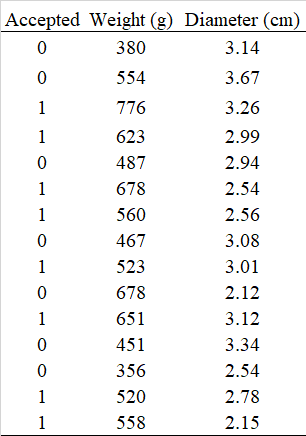

%% Logistic Regression Example: Weight & Diameter -> Accepted
% Full corrected version. This includes a sanity check on vector lengths
% (the error you saw comes from mismatched lengths).

%% Step 1. Input the data (make sure each vector has the same number of rows)
Accepted = [0, 0, 1, 1, 0, 1, 1, 0, 1, 0, 1, 0, 0, 1, 1]';
Weight   = [380, 554, 776, 623, 487, 678, 560, 467, 523, 678, 651, 451, 356, 520, 558]';
Diameter = [3.14, 3.67, 3.26, 2.99, 2.94, 2.54, 2.56, 3.08, 3.01, 2.12, 3.12, 3.34, 2.54, 2.78, 2.15]';

% Sanity check — helpful debug line to prevent the "All table variables must have the same number of rows" error
nA = numel(Accepted); nW = numel(Weight); nD = numel(Diameter);
assert(nA==nW && nW==nD, ...
    sprintf('Vector lengths mismatch: Accepted=%d Weight=%d Diameter=%d', nA, nW, nD));

% Create the table
data = table(Accepted, Weight, Diameter);

%% Step 2. Fit a logistic regression model
% Model: logit(p) = b0 + b1*Weight + b2*Diameter
model = fitglm(data, 'Accepted ~ Weight + Diameter', ...
               'Distribution', 'binomial', 'Link', 'logit');

disp('--- Model summary ---')

--- Model summary ---


disp(model)     % shows coefficients, deviance, etc.


Generalized linear regression model:
    logit(Accepted) ~ 1 + Weight + Diameter
    Distribution = Binomial

Estimated Coefficients:
                   Estimate       SE         tStat       pValue 
                   ________    _________    ________    ________

    (Intercept)      -5.353        6.725    -0.79599     0.42604
    Weight          0.01431    0.0079947      1.7899    0.073473
    Diameter       -0.79434       1.5895    -0.49973     0.61726


15 observations, 12 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 6.17, p-value = 0.0457



%% Step 3. Extract coefficients (vector form)
b = model.Coefficients.Estimate;   % [b0; b1; b2]
b0 = b(1); b1 = b(2); b2 = b(3);
fprintf('Intercept b0 = %.6f; b1 (Weight) = %.6f; b2 (Diameter) = %.6f\n', b0, b1, b2);

Intercept b0 = -5.353037; b1 (Weight) = 0.014310; b2 (Diameter) = -0.794337



%% Step 4. Calculate Logit, e^L, P(X), and LL for each observation
% Use design matrix to ensure we compute the same linear predictor as the model
X = [ones(nA,1), Weight, Diameter];        % n x 3
logit_calculated = X * b;                  % linear predictor L = b0 + b1*x1 + b2*x2

eL_calculated = exp(logit_calculated);     % e^L
PX_calculated = eL_calculated ./ (1 + eL_calculated);  % probability P(X)
LL_calculated = Accepted .* log(PX_calculated) + ...
                (1 - Accepted) .* log(1 - PX_calculated);% log-likelihood contributions

%% Step 5. Append the calculated columns to the table and display
data.Logit_L = logit_calculated;
data.eL      = eL_calculated;
data.PX      = PX_calculated;
data.LL      = LL_calculated;

disp('--- Data with calculated columns ---')

--- Data with calculated columns ---


disp(data)

    Accepted    Weight    Diameter    Logit_L        eL          PX          LL    
    ________    ______    ________    ________    ________    ________    _________

       0         380        3.14       -2.4096    0.089852    0.082444    -0.086042
       0         554        3.67      -0.34071     0.71127     0.41564     -0.53723
       1         776        3.26        3.1617      23.611     0.95937    -0.041481
       1         623        2.99        1.1868      3.2766     0.76617     -0.26635
       0         487        2.94      -0.71959     0.48695     0.32748     -0.39673
       1         678        2.54        2.3313      10.291     0.91144    -0.092735
       1         560        2.56       0.62686      1.8717     0.65178     -0.42805
     


%% Step 6. Predict for a new observation (Weight = 150, Diameter = 3.31)
newPoint = table(150, 3.31, 'VariableNames', {'Weight','Diameter'});  % 1x2 table

[predictedProb, CI] = predict(model, newPoint);   % predictedProb is P(accepted=1)
fprintf('\nPredicted probability of acceptance (1): %.6f\n', predictedProb);


Predicted probability of acceptance (1): 0.002912


fprintf('Predicted probability of rejection (0): %.6f\n', 1 - predictedProb);

Predicted probability of rejection (0): 0.997088



% Binary classification using 0.5 threshold
binary_response = predictedProb >= 0.5;
fprintf('Binary Prediction (0=Rejected, 1=Accepted): %d\n', binary_response);

Binary Prediction (0=Rejected, 1=Accepted): 0



%% Optional: show confidence interval returned by predict
disp('95% CI for predicted mean (on response scale):')

95% CI for predicted mean (on response scale):


disp(CI)

    0.0000    0.5899



# EXAMPLE  Quadratic Regression Exercise

Suppose we are interested in understanding the relationship between number of hours worked and reported happiness. We have the following data on the number of hours worked per week and the reported happiness level (on a scale of 0-100) for 11 different people:

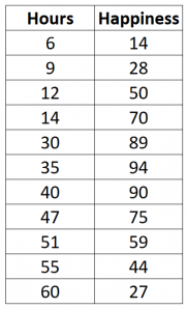

- Create a dataframe with the provided data.

- Visualise the data

- Fit a quadratic regression model and visualise the results

- Evaluate your model

- Predict the happiness value for the 70 and 75 hours of working

- Compare your results with the results on the following link: [https://www.statology.org/quadratic-regression-r/](https://www.statology.org/quadratic-regression-r/)

Reference: [https://www.statology.org/quadratic-regression-r/](https://www.statology.org/quadratic-regression-r/)

%Please complete the code yourself and the solution will be available by
%the end of the week 3. 